# REPRESENTACIÓN DE PROPIEDADES DE SOFA

## OBTENCIÓN DE DATOS DE SOFA

% Cargamos los datos desde un archivo dado que el tiempo de simulación es
% muy alto
% load("matlab.mat");

% Desglosamos los valores en sus respectivas componentes
[vector_tiempo_6_5,posicion_nodo_0_dcha_6_5,posicion_nodo_28_central_6_5,posicion_nodo_56_izq_6_5] = readvars('properties_0-28-56_6.5_x.txt');
[vector_tiempo_7,posicion_nodo_0_dcha_7,posicion_nodo_28_central_7,posicion_nodo_56_izq_7] = readvars('properties_0-28-56_7_x.txt');
[vector_tiempo_7_5,posicion_nodo_0_dcha_7_5,posicion_nodo_28_central_7_5,posicion_nodo_56_izq_7_5] = readvars('properties_0-28-56_7.5_x.txt');
[vector_tiempo_7_8,posicion_nodo_0_dcha_7_8,posicion_nodo_28_central_7_8,posicion_nodo_56_izq_7_8] = readvars('properties_0-28-56_7.8_x.txt');
[vector_tiempo_8,posicion_nodo_0_dcha_8,posicion_nodo_28_central_8,posicion_nodo_56_izq_8] = readvars('properties_0-28-56_8_x.txt');
[vector_tiempo_8_2,posicion_nodo_0_dcha_8_2,posicion_nodo_28_central_8_2,posicion_nodo_56_izq_8_2] = readvars('properties_0-28-56_8.2_x.txt');
[vector_tiempo_8_4,posicion_nodo_0_dcha_8_4,posicion_nodo_28_central_8_4,posicion_nodo_56_izq_8_4] = readvars('properties_0-28-56_8.4_x.txt');
[vector_tiempo_8_5,posicion_nodo_0_dcha_8_5,posicion_nodo_28_central_8_5,posicion_nodo_56_izq_8_5] = readvars('properties_0-28-56_8.5_x.txt');
[vector_tiempo_9,posicion_nodo_0_dcha_9,posicion_nodo_28_central_9,posicion_nodo_56_izq_9] = readvars('properties_0-28-56_9_x.txt');
[vector_tiempo_9_5,posicion_nodo_0_dcha_9_5,posicion_nodo_28_central_9_5,posicion_nodo_56_izq_9_5] = readvars('properties_0-28-56_9.5_x.txt');

 % Expresion que ayuda a dividir la celda cada que encontramos un espacio en el vector
expression = ' ';

% Dividimos la cadena en la misma variable pero con celdas separadas según
% hemos indicado en la variable expresión. Es decir que ashora por cada
% fila tendremos a su vez una celda dividida en 7 celdas más pequeñas
posicion_nodo_0_dcha_split_6_5 = regexp(posicion_nodo_0_dcha_6_5,expression,'split');
posicion_nodo_28_central_split_6_5 = regexp(posicion_nodo_28_central_6_5,expression,'split');
posicion_nodo_56_izq_split_6_5 = regexp(posicion_nodo_56_izq_6_5,expression,'split');

posicion_nodo_0_dcha_split_7 = regexp(posicion_nodo_0_dcha_7,expression,'split');
posicion_nodo_28_central_split_7 = regexp(posicion_nodo_28_central_7,expression,'split');
posicion_nodo_56_izq_split_7 = regexp(posicion_nodo_56_izq_7,expression,'split');

posicion_nodo_0_dcha_split_7_5 = regexp(posicion_nodo_0_dcha_7_5,expression,'split');
posicion_nodo_28_central_split_7_5 = regexp(posicion_nodo_28_central_7_5,expression,'split');
posicion_nodo_56_izq_split_7_5 = regexp(posicion_nodo_56_izq_7_5,expression,'split');

posicion_nodo_0_dcha_split_7_8 = regexp(posicion_nodo_0_dcha_7_8,expression,'split');
posicion_nodo_28_central_split_7_8 = regexp(posicion_nodo_28_central_7_8,expression,'split');
posicion_nodo_56_izq_split_7_8 = regexp(posicion_nodo_56_izq_7_8,expression,'split');

posicion_nodo_0_dcha_split_8 = regexp(posicion_nodo_0_dcha_8,expression,'split');
posicion_nodo_28_central_split_8 = regexp(posicion_nodo_28_central_8,expression,'split');
posicion_nodo_56_izq_split_8 = regexp(posicion_nodo_56_izq_8,expression,'split');

posicion_nodo_0_dcha_split_8_2 = regexp(posicion_nodo_0_dcha_8_2,expression,'split');
posicion_nodo_28_central_split_8_2 = regexp(posicion_nodo_28_central_8_2,expression,'split');
posicion_nodo_56_izq_split_8_2 = regexp(posicion_nodo_56_izq_8_2,expression,'split');

posicion_nodo_0_dcha_split_8_4 = regexp(posicion_nodo_0_dcha_8_4,expression,'split');
posicion_nodo_28_central_split_8_4 = regexp(posicion_nodo_28_central_8_4,expression,'split');
posicion_nodo_56_izq_split_8_4 = regexp(posicion_nodo_56_izq_8_4,expression,'split');

posicion_nodo_0_dcha_split_8_5 = regexp(posicion_nodo_0_dcha_8_5,expression,'split');
posicion_nodo_28_central_split_8_5 = regexp(posicion_nodo_28_central_8_5,expression,'split');
posicion_nodo_56_izq_split_8_5 = regexp(posicion_nodo_56_izq_8_5,expression,'split');

posicion_nodo_0_dcha_split_9 = regexp(posicion_nodo_0_dcha_9,expression,'split');
posicion_nodo_28_central_split_9 = regexp(posicion_nodo_28_central_9,expression,'split');
posicion_nodo_56_izq_split_9 = regexp(posicion_nodo_56_izq_9,expression,'split');

posicion_nodo_0_dcha_split_9_5 = regexp(posicion_nodo_0_dcha_9_5,expression,'split');
posicion_nodo_28_central_split_9_5 = regexp(posicion_nodo_28_central_9_5,expression,'split');
posicion_nodo_56_izq_split_9_5 = regexp(posicion_nodo_56_izq_9_5,expression,'split');

% Recolectamos los datos y los metemos en una matriz
for i=1:length(posicion_nodo_0_dcha_split_6_5)
    
    % Guardamos el valor de la celda en una variable
    posicion_nodo_0_dcha_split_6_5_ = posicion_nodo_0_dcha_split_6_5{i,1};
    posicion_nodo_28_central_split_6_5_ = posicion_nodo_28_central_split_6_5{i,1};
    posicion_nodo_56_izq_split_6_5_ = posicion_nodo_56_izq_split_6_5{i,1};
    
    % Entramos en la subcelda y metemos cada valor de la fila en una
    % matriz, convirtiéndolo en un valor numérico
    for j=1:length(posicion_nodo_0_dcha_split_6_5_)
        
        posicion_nodo_0_dcha_split_num_6_5 = cell2mat(posicion_nodo_0_dcha_split_6_5_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_6_5 = cell2mat(posicion_nodo_28_central_split_6_5_(1,j));
        posicion_nodo_56_izq_split_num_6_5 = cell2mat(posicion_nodo_56_izq_split_6_5_(1,j));
        
        posiciones_nodo_0_6_5(i,j) = str2double(posicion_nodo_0_dcha_split_num_6_5);
        posiciones_nodo_28_6_5(i,j) = str2double(posicion_nodo_28_central_split_num_6_5);
        posiciones_nodo_56_6_5(i,j) = str2double(posicion_nodo_56_izq_split_num_6_5);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_7)
    
    posicion_nodo_0_dcha_split_7_ = posicion_nodo_0_dcha_split_7{i,1};
    posicion_nodo_28_central_split_7_ = posicion_nodo_28_central_split_7{i,1};
    posicion_nodo_56_izq_split_7_ = posicion_nodo_56_izq_split_7{i,1};
    
    for j=1:length(posicion_nodo_0_dcha_split_7_)
        
        posicion_nodo_0_dcha_split_num_7 = cell2mat(posicion_nodo_0_dcha_split_7_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_7 = cell2mat(posicion_nodo_28_central_split_7_(1,j));
        posicion_nodo_56_izq_split_num_7 = cell2mat(posicion_nodo_56_izq_split_7_(1,j));
        
        posiciones_nodo_0_7(i,j) = str2double(posicion_nodo_0_dcha_split_num_7);
        posiciones_nodo_28_7(i,j) = str2double(posicion_nodo_28_central_split_num_7);
        posiciones_nodo_56_7(i,j) = str2double(posicion_nodo_56_izq_split_num_7);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_7_5)
    
    posicion_nodo_0_dcha_split_7_5_ = posicion_nodo_0_dcha_split_7_5{i,1};
    posicion_nodo_28_central_split_7_5_ = posicion_nodo_28_central_split_7_5{i,1};
    posicion_nodo_56_izq_split_7_5_ = posicion_nodo_56_izq_split_7_5{i,1};
    
    for j=1:length(posicion_nodo_0_dcha_split_7_5_)
        
        posicion_nodo_0_dcha_split_num_7_5 = cell2mat(posicion_nodo_0_dcha_split_7_5_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_7_5 = cell2mat(posicion_nodo_28_central_split_7_5_(1,j));
        posicion_nodo_56_izq_split_num_7_5 = cell2mat(posicion_nodo_56_izq_split_7_5_(1,j));
        
        posiciones_nodo_0_7_5(i,j) = str2double(posicion_nodo_0_dcha_split_num_7_5);
        posiciones_nodo_28_7_5(i,j) = str2double(posicion_nodo_28_central_split_num_7_5);
        posiciones_nodo_56_7_5(i,j) = str2double(posicion_nodo_56_izq_split_num_7_5);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_7_8)
    
    posicion_nodo_0_dcha_split_7_8_ = posicion_nodo_0_dcha_split_7_8{i,1};
    posicion_nodo_28_central_split_7_8_ = posicion_nodo_28_central_split_7_8{i,1};
    posicion_nodo_56_izq_split_7_8_ = posicion_nodo_56_izq_split_7_8{i,1};

    for j=1:length(posicion_nodo_0_dcha_split_7_8_)
        
        posicion_nodo_0_dcha_split_num_7_8 = cell2mat(posicion_nodo_0_dcha_split_7_8_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_7_8 = cell2mat(posicion_nodo_28_central_split_7_8_(1,j));
        posicion_nodo_56_izq_split_num_7_8 = cell2mat(posicion_nodo_56_izq_split_7_8_(1,j));
        
        posiciones_nodo_0_7_8(i,j) = str2double(posicion_nodo_0_dcha_split_num_7_8);
        posiciones_nodo_28_7_8(i,j) = str2double(posicion_nodo_28_central_split_num_7_8);
        posiciones_nodo_56_7_8(i,j) = str2double(posicion_nodo_56_izq_split_num_7_8);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_8_2)
    
    posicion_nodo_0_dcha_split_8_2_ = posicion_nodo_0_dcha_split_8_2{i,1};
    posicion_nodo_28_central_split_8_2_ = posicion_nodo_28_central_split_8_2{i,1};
    posicion_nodo_56_izq_split_8_2_ = posicion_nodo_56_izq_split_8_2{i,1};

    for j=1:length(posicion_nodo_0_dcha_split_8_2_)
        
        posicion_nodo_0_dcha_split_num_8_2 = cell2mat(posicion_nodo_0_dcha_split_8_2_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_8_2 = cell2mat(posicion_nodo_28_central_split_8_2_(1,j));
        posicion_nodo_56_izq_split_num_8_2 = cell2mat(posicion_nodo_56_izq_split_8_2_(1,j));
        
        posiciones_nodo_0_8_2(i,j) = str2double(posicion_nodo_0_dcha_split_num_8_2);
        posiciones_nodo_28_8_2(i,j) = str2double(posicion_nodo_28_central_split_num_8_2);
        posiciones_nodo_56_8_2(i,j) = str2double(posicion_nodo_56_izq_split_num_8_2);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_8)
    
    posicion_nodo_0_dcha_split_8_ = posicion_nodo_0_dcha_split_8{i,1};
    posicion_nodo_28_central_split_8_ = posicion_nodo_28_central_split_8{i,1};
    posicion_nodo_56_izq_split_8_ = posicion_nodo_56_izq_split_8{i,1};

    for j=1:length(posicion_nodo_0_dcha_split_8_)
        
        posicion_nodo_0_dcha_split_num_8 = cell2mat(posicion_nodo_0_dcha_split_8_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_8 = cell2mat(posicion_nodo_28_central_split_8_(1,j));
        posicion_nodo_56_izq_split_num_8 = cell2mat(posicion_nodo_56_izq_split_8_(1,j));
        
        posiciones_nodo_0_8(i,j) = str2double(posicion_nodo_0_dcha_split_num_8);
        posiciones_nodo_28_8(i,j) = str2double(posicion_nodo_28_central_split_num_8);
        posiciones_nodo_56_8(i,j) = str2double(posicion_nodo_56_izq_split_num_8);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_8_4)
    
    posicion_nodo_0_dcha_split_8_4_ = posicion_nodo_0_dcha_split_8_4{i,1};
    posicion_nodo_28_central_split_8_4_ = posicion_nodo_28_central_split_8_4{i,1};
    posicion_nodo_56_izq_split_8_4_ = posicion_nodo_56_izq_split_8_4{i,1};
    
    for j=1:length(posicion_nodo_0_dcha_split_8_4_)
        
        posicion_nodo_0_dcha_split_num_8_4 = cell2mat(posicion_nodo_0_dcha_split_8_4_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_8_4 = cell2mat(posicion_nodo_28_central_split_8_4_(1,j));
        posicion_nodo_56_izq_split_num_8_4 = cell2mat(posicion_nodo_56_izq_split_8_4_(1,j));
        
        posiciones_nodo_0_8_4(i,j) = str2double(posicion_nodo_0_dcha_split_num_8_4);
        posiciones_nodo_28_8_4(i,j) = str2double(posicion_nodo_28_central_split_num_8_4);
        posiciones_nodo_56_8_4(i,j) = str2double(posicion_nodo_56_izq_split_num_8_4);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_8_5)
    
    posicion_nodo_0_dcha_split_8_5_ = posicion_nodo_0_dcha_split_8_5{i,1};
    posicion_nodo_28_central_split_8_5_ = posicion_nodo_28_central_split_8_5{i,1};
    posicion_nodo_56_izq_split_8_5_ = posicion_nodo_56_izq_split_8_5{i,1};
    
    for j=1:length(posicion_nodo_0_dcha_split_8_5_)
        
        posicion_nodo_0_dcha_split_num_8_5 = cell2mat(posicion_nodo_0_dcha_split_8_5_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_8_5 = cell2mat(posicion_nodo_28_central_split_8_5_(1,j));
        posicion_nodo_56_izq_split_num_8_5 = cell2mat(posicion_nodo_56_izq_split_8_5_(1,j));
        
        posiciones_nodo_0_8_5(i,j) = str2double(posicion_nodo_0_dcha_split_num_8_5);
        posiciones_nodo_28_8_5(i,j) = str2double(posicion_nodo_28_central_split_num_8_5);
        posiciones_nodo_56_8_5(i,j) = str2double(posicion_nodo_56_izq_split_num_8_5);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_9)
    
    posicion_nodo_0_dcha_split_9_ = posicion_nodo_0_dcha_split_9{i,1};
    posicion_nodo_28_central_split_9_ = posicion_nodo_28_central_split_9{i,1};
    posicion_nodo_56_izq_split_9_ = posicion_nodo_56_izq_split_9{i,1};
    
    for j=1:length(posicion_nodo_0_dcha_split_9_)
        
        posicion_nodo_0_dcha_split_num_9 = cell2mat(posicion_nodo_0_dcha_split_9_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_9 = cell2mat(posicion_nodo_28_central_split_9_(1,j));
        posicion_nodo_56_izq_split_num_9 = cell2mat(posicion_nodo_56_izq_split_9_(1,j));
        
        posiciones_nodo_0_9(i,j) = str2double(posicion_nodo_0_dcha_split_num_9);
        posiciones_nodo_28_9(i,j) = str2double(posicion_nodo_28_central_split_num_9);
        posiciones_nodo_56_9(i,j) = str2double(posicion_nodo_56_izq_split_num_9);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_9_5)
    
    posicion_nodo_0_dcha_split_9_5_ = posicion_nodo_0_dcha_split_9_5{i,1};
    posicion_nodo_28_central_split_9_5_ = posicion_nodo_28_central_split_9_5{i,1};
    posicion_nodo_56_izq_split_9_5_ = posicion_nodo_56_izq_split_9_5{i,1};

    for j=1:length(posicion_nodo_0_dcha_split_9_5_)
        
        posicion_nodo_0_dcha_split_num_9_5 = cell2mat(posicion_nodo_0_dcha_split_9_5_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_9_5 = cell2mat(posicion_nodo_28_central_split_9_5_(1,j));
        posicion_nodo_56_izq_split_num_9_5 = cell2mat(posicion_nodo_56_izq_split_9_5_(1,j));
        
        posiciones_nodo_0_9_5(i,j) = str2double(posicion_nodo_0_dcha_split_num_9_5);
        posiciones_nodo_28_9_5(i,j) = str2double(posicion_nodo_28_central_split_num_9_5);
        posiciones_nodo_56_9_5(i,j) = str2double(posicion_nodo_56_izq_split_num_9_5);
    end
end

## HALLAMOS EL VALOR MÁXIMO Y MÍNIMO DE DESPLAZAMIENTO

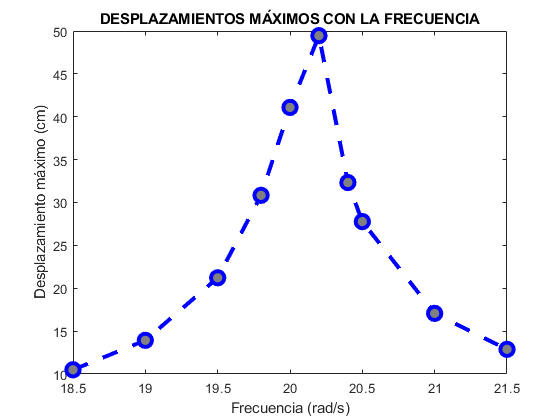

% Todas las posiciones están en metros, salvo la última sentencia

% Concatenamos los vectores del tiempo y las posiciones recogidas de los
% nodos estudiados para detectar dónde se encuentra el máximo y el mínimo
posicion_0_6_5_ = [vector_tiempo_6_5 posiciones_nodo_0_6_5];
posicion_28_6_5_ = [vector_tiempo_6_5 posiciones_nodo_28_6_5];
posicion_56_6_5_ = [vector_tiempo_6_5 posiciones_nodo_56_6_5];

posicion_0_7_ = [vector_tiempo_7 posiciones_nodo_0_7];
posicion_28_7_ = [vector_tiempo_7 posiciones_nodo_28_7];
posicion_56_7_ = [vector_tiempo_7 posiciones_nodo_56_7];

posicion_0_7_5_ = [vector_tiempo_7_5 posiciones_nodo_0_7_5];
posicion_28_7_5_ = [vector_tiempo_7_5 posiciones_nodo_28_7_5];
posicion_56_7_5_ = [vector_tiempo_7_5 posiciones_nodo_56_7_5];

posicion_0_7_8_ = [vector_tiempo_7_8 posiciones_nodo_0_7_8];
posicion_28_7_8_ = [vector_tiempo_7_8 posiciones_nodo_28_7_8];
posicion_56_7_8_ = [vector_tiempo_7_8 posiciones_nodo_56_7_8];

posicion_0_8_ = [vector_tiempo_8 posiciones_nodo_0_8];
posicion_28_8_ = [vector_tiempo_8 posiciones_nodo_28_8];
posicion_56_8_ = [vector_tiempo_8 posiciones_nodo_56_8];

posicion_0_8_2_ = [vector_tiempo_8_2 posiciones_nodo_0_8_2];
posicion_28_8_2_ = [vector_tiempo_8_2 posiciones_nodo_28_8_2];
posicion_56_8_2_ = [vector_tiempo_8_2 posiciones_nodo_56_8_2];

posicion_0_8_4_ = [vector_tiempo_8_4 posiciones_nodo_0_8_4];
posicion_28_8_4_ = [vector_tiempo_8_4 posiciones_nodo_28_8_4];
posicion_56_8_4_ = [vector_tiempo_8_4 posiciones_nodo_56_8_4];

posicion_0_8_5_ = [vector_tiempo_8_5 posiciones_nodo_0_8_5];
posicion_28_8_5_ = [vector_tiempo_8_5 posiciones_nodo_28_8_5];
posicion_56_8_5_ = [vector_tiempo_8_5 posiciones_nodo_56_8_5];

posicion_0_9_ = [vector_tiempo_9 posiciones_nodo_0_9];
posicion_28_9_ = [vector_tiempo_9 posiciones_nodo_28_9];
posicion_56_9_ = [vector_tiempo_9 posiciones_nodo_56_9];

posicion_0_9_5_ = [vector_tiempo_9_5 posiciones_nodo_0_9_5];
posicion_28_9_5_ = [vector_tiempo_9_5 posiciones_nodo_28_9_5];
posicion_56_9_5_ = [vector_tiempo_9_5 posiciones_nodo_56_9_5];

% Obtenemos el máximo y mínimo de los tres nodos
M_0_6_5 = max(posicion_0_6_5_(:,4));
m_0_6_5 = min(posicion_0_6_5_(:,4));
M_28_6_5 = max(posicion_28_6_5_(:,4));
m_28_6_5 = min(posicion_28_6_5_(:,4));
M_56_6_5 = max(posicion_56_6_5_(:,4));
m_56_6_5 = min(posicion_56_6_5_(:,4));

M_0_7 = max(posicion_0_7_(:,4));
m_0_7 = min(posicion_0_7_(:,4));
M_28_7 = max(posicion_28_7_(:,4));
m_28_7 = min(posicion_28_7_(:,4));
M_56_7 = max(posicion_56_7_(:,4));
m_56_7 = min(posicion_56_7_(:,4));

M_0_7_5 = max(posicion_0_7_5_(:,4));
m_0_7_5 = min(posicion_0_7_5_(:,4));
M_28_7_5 = max(posicion_28_7_5_(:,4));
m_28_7_5 = min(posicion_28_7_5_(:,4));
M_56_7_5 = max(posicion_56_7_5_(:,4));
m_56_7_5 = min(posicion_56_7_5_(:,4));

M_0_7_8 = max(posicion_0_7_8_(:,4));
m_0_7_8 = min(posicion_0_7_8_(:,4));
M_28_7_8 = max(posicion_28_7_8_(:,4));
m_28_7_8 = min(posicion_28_7_8_(:,4));
M_56_7_8 = max(posicion_56_7_8_(:,4));
m_56_7_8 = min(posicion_56_7_8_(:,4));

M_0_8 = max(posicion_0_8_(:,4));
m_0_8 = min(posicion_0_8_(:,4));
M_28_8 = max(posicion_28_8_(:,4));
m_28_8 = min(posicion_28_8_(:,4));
M_56_8 = max(posicion_56_8_(:,4));
m_56_8 = min(posicion_56_8_(:,4));

M_0_8_2 = max(posicion_0_8_2_(:,4));
m_0_8_2 = min(posicion_0_8_2_(:,4));
M_28_8_2 = max(posicion_28_8_2_(:,4));
m_28_8_2 = min(posicion_28_8_2_(:,4));
M_56_8_2 = max(posicion_56_8_2_(:,4));
m_56_8_2 = min(posicion_56_8_2_(:,4));

M_0_8_4 = max(posicion_0_8_4_(:,4));
m_0_8_4 = min(posicion_0_8_4_(:,4));
M_28_8_4 = max(posicion_28_8_4_(:,4));
m_28_8_4 = min(posicion_28_8_4_(:,4));
M_56_8_4 = max(posicion_56_8_4_(:,4));
m_56_8_4 = min(posicion_56_8_4_(:,4));

M_0_8_5 = max(posicion_0_8_5_(:,4));
m_0_8_5 = min(posicion_0_8_5_(:,4));
M_28_8_5 = max(posicion_28_8_5_(:,4));
m_28_8_5 = min(posicion_28_8_5_(:,4));
M_56_8_5 = max(posicion_56_8_5_(:,4));
m_56_8_5 = min(posicion_56_8_5_(:,4));

M_0_9 = max(posicion_0_9_(:,4));
m_0_9 = min(posicion_0_9_(:,4));
M_28_9 = max(posicion_28_9_(:,4));
m_28_9 = min(posicion_28_9_(:,4));
M_56_9 = max(posicion_56_9_(:,4));
m_56_9 = min(posicion_56_9_(:,4));

M_0_9_5 = max(posicion_0_9_5_(:,4));
m_0_9_5 = min(posicion_0_9_5_(:,4));
M_28_9_5 = max(posicion_28_9_5_(:,4));
m_28_9_5 = min(posicion_28_9_5_(:,4));
M_56_9_5 = max(posicion_56_9_5_(:,4));
m_56_9_5 = min(posicion_56_9_5_(:,4));

% Detectamos el tiempo para el cual se ha alcanzado el mínimo y lo
% guardamos en una variable auxiliar
for i=1:length(posicion_nodo_0_dcha_split_6_5)
    if (m_0_6_5==posicion_0_6_5_(i,4))

        tiempo_0_6_5 = posicion_0_6_5_(i,1);
    end
    if (m_56_6_5==posicion_56_6_5_(i,4))

        tiempo_56_6_5 = posicion_56_6_5_(i,1);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_7)
    if (m_0_7==posicion_0_7_(i,4))

        tiempo_0_7 = posicion_0_7_(i,1);
    end
    if (m_56_7==posicion_56_7_(i,4))

        tiempo_56_7 = posicion_56_7_(i,1);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_7_5)
    if (m_0_7_5==posicion_0_7_5_(i,4))

        tiempo_0_7_5 = posicion_0_7_5_(i,1);
    end
    if (m_56_7_5==posicion_56_7_5_(i,4))

        tiempo_56_7_5 = posicion_56_7_5_(i,1);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_7_8)
    if (m_0_7_8==posicion_0_7_8_(i,4))

        tiempo_0_7_8 = posicion_0_7_8_(i,1);
    end
    if (m_56_7_8==posicion_56_7_8_(i,4))

        tiempo_56_7_8 = posicion_56_7_8_(i,1);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_8)
    if (m_0_8==posicion_0_8_(i,4))

        tiempo_0_8 = posicion_0_8_(i,1);
    end
    if (m_56_8==posicion_56_8_(i,4))

        tiempo_56_8 = posicion_56_8_(i,1);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_8_2)
    if (m_0_8_2==posicion_0_8_2_(i,4))

        tiempo_0_8_2 = posicion_0_8_2_(i,1);
    end
    if (m_56_8_2==posicion_56_8_2_(i,4))

        tiempo_56_8_2 = posicion_56_8_2_(i,1);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_8_4)
    if (m_0_8_4==posicion_0_8_4_(i,4))

        tiempo_0_8_4 = posicion_0_8_4_(i,1);
    end
    if (m_56_8_4==posicion_56_8_4_(i,4))

        tiempo_56_8_4 = posicion_56_8_4_(i,1);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_8_5)
    if (m_0_8_5==posicion_0_8_5_(i,4))

        tiempo_0_8_5 = posicion_0_8_5_(i,1);
    end
    if (m_56_8_5==posicion_56_8_5_(i,4))

        tiempo_56_8_5 = posicion_56_8_5_(i,1);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_9)
    if (m_0_9==posicion_0_9_(i,4))

        tiempo_0_9 = posicion_0_9_(i,1);
    end
    if (m_56_9==posicion_56_9_(i,4))

        tiempo_56_9 = posicion_56_9_(i,1);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_9_5)
    if (m_0_9_5==posicion_0_9_5_(i,4))

        tiempo_0_9_5 = posicion_0_9_5_(i,1);
    end
    if (m_56_9_5==posicion_56_9_5_(i,4))

        tiempo_56_9_5 = posicion_56_9_5_(i,1);
    end
end

% Para dicho tiempo, cogemos la posición del nodo central
for i=1:length(posicion_nodo_0_dcha_split_6_5)
    if (tiempo_0_6_5==posicion_28_6_5_(i,1))

        posicion_resta_6_5 = posicion_28_6_5_(i,4);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_7)
    if (tiempo_0_7==posicion_28_7_(i,1))

        posicion_resta_7 = posicion_28_7_(i,4);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_7_5)
    if (tiempo_0_7_5==posicion_28_7_5_(i,1))

        posicion_resta_7_5 = posicion_28_7_5_(i,4);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_7_8)
    if (tiempo_0_7_8==posicion_28_7_8_(i,1))

        posicion_resta_7_8 = posicion_28_7_8_(i,4);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_8)
    if (tiempo_0_8==posicion_28_8_(i,1))

        posicion_resta_8 = posicion_28_8_(i,4);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_8_2)
    if (tiempo_0_8_2==posicion_28_8_2_(i,1))

        posicion_resta_8_2 = posicion_28_8_2_(i,4);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_8_4)
    if (tiempo_0_8_4==posicion_28_8_4_(i,1))

        posicion_resta_8_4 = posicion_28_8_4_(i,4);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_8_5)
    if (tiempo_0_8_5==posicion_28_8_5_(i,1))

        posicion_resta_8_5 = posicion_28_8_5_(i,4);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_9)
    if (tiempo_0_9==posicion_28_9_(i,1))

        posicion_resta_9 = posicion_28_9_(i,4);
    end
end
for i=1:length(posicion_nodo_0_dcha_split_9_5)
    if (tiempo_0_9_5==posicion_28_9_5_(i,1))

        posicion_resta_9_5 = posicion_28_9_5_(i,4);
    end
end

% Una vez con dicha posición del nodo central, podemos obtener de una
% manera más precisa cuál es el desplazamiento máximo, medido como la
% distancia que hay del nodo central a ambos puntos extremos de la barra
% Unidades en cm
desplazamiento_real_derecho_6_5 = (abs(m_0_6_5) + posicion_resta_6_5)*100;
desplazamiento_real_izquierdo_6_5 = (abs(m_56_6_5) + posicion_resta_6_5)*100;
desplazamiento_6_5 = [desplazamiento_real_derecho_6_5 desplazamiento_real_izquierdo_6_5];
desplazamiento_medio_6_5 = mean(desplazamiento_6_5);

desplazamiento_real_derecho_7 = (abs(m_0_7) + posicion_resta_7)*100;
desplazamiento_real_izquierdo_7 = (abs(m_56_7) + posicion_resta_7)*100;
desplazamiento_7 = [desplazamiento_real_derecho_7 desplazamiento_real_izquierdo_7];
desplazamiento_medio_7 = mean(desplazamiento_7);

desplazamiento_real_derecho_7_5 = (abs(m_0_7_5) + posicion_resta_7_5)*100;
desplazamiento_real_izquierdo_7_5 = (abs(m_56_7_5) + posicion_resta_7_5)*100;
desplazamiento_7_5 = [desplazamiento_real_derecho_7_5 desplazamiento_real_izquierdo_7_5];
desplazamiento_medio_7_5 = mean(desplazamiento_7_5);

desplazamiento_real_derecho_7_8 = (abs(m_0_7_8) + posicion_resta_7_8)*100;
desplazamiento_real_izquierdo_7_8 = (abs(m_56_7_8) + posicion_resta_7_8)*100;
desplazamiento_7_8 = [desplazamiento_real_derecho_7_8 desplazamiento_real_izquierdo_7_8];
desplazamiento_medio_7_8 = mean(desplazamiento_7_8);

desplazamiento_real_derecho_8 = (abs(m_0_8) + posicion_resta_8)*100;
desplazamiento_real_izquierdo_8 = (abs(m_56_8) + posicion_resta_8)*100;
desplazamiento_8 = [desplazamiento_real_derecho_8 desplazamiento_real_izquierdo_8];
desplazamiento_medio_8 = mean(desplazamiento_8);

desplazamiento_real_derecho_8_2 = (abs(m_0_8_2) + posicion_resta_8_2)*100;
desplazamiento_real_izquierdo_8_2 = (abs(m_56_8_2) + posicion_resta_8_2)*100;
desplazamiento_8_2 = [desplazamiento_real_derecho_8_2 desplazamiento_real_izquierdo_8_2];
desplazamiento_medio_8_2 = mean(desplazamiento_8_2);

desplazamiento_real_derecho_8_4 = (abs(m_0_8_4) + posicion_resta_8_4)*100;
desplazamiento_real_izquierdo_8_4 = (abs(m_56_8_4) + posicion_resta_8_4)*100;
desplazamiento_8_4 = [desplazamiento_real_derecho_8_4 desplazamiento_real_izquierdo_8_4];
desplazamiento_medio_8_4 = mean(desplazamiento_8_4);

desplazamiento_real_derecho_8_5 = (abs(m_0_8_5) + posicion_resta_8_5)*100;
desplazamiento_real_izquierdo_8_5 = (abs(m_56_8_5) + posicion_resta_8_5)*100;
desplazamiento_8_5 = [desplazamiento_real_derecho_8_5 desplazamiento_real_izquierdo_8_5];
desplazamiento_medio_8_5 = mean(desplazamiento_8_5);

desplazamiento_real_derecho_9 = (abs(m_0_9) + posicion_resta_9)*100;
desplazamiento_real_izquierdo_9 = (abs(m_56_9) + posicion_resta_9)*100;
desplazamiento_9 = [desplazamiento_real_derecho_9 desplazamiento_real_izquierdo_9];
desplazamiento_medio_9 = mean(desplazamiento_9);

desplazamiento_real_derecho_9_5 = (abs(m_0_9_5) + posicion_resta_9_5)*100;
desplazamiento_real_izquierdo_9_5 = (abs(m_56_9_5) + posicion_resta_9_5)*100;
desplazamiento_9_5 = [desplazamiento_real_derecho_9_5 desplazamiento_real_izquierdo_9_5];
desplazamiento_medio_9_5 = mean(desplazamiento_9_5);

% Almacenamos el valor a mano de las frecuencias estudiadas en SOFA
pares = [6.5 7 7.5 7.8 8 8.2 8.4 8.5 9 9.5];
frecuencias = [18.48 19.04];
% Almacenamos el valor de los desplazamientos obtenidos
desp = [desplazamiento_medio_6_5 desplazamiento_medio_7 desplazamiento_medio_7_5 desplazamiento_medio_7_8 desplazamiento_medio_8 desplazamiento_medio_8_2 desplazamiento_medio_8_4 desplazamiento_medio_8_5 desplazamiento_medio_9 desplazamiento_medio_9_5];

% Representamos dichos valores de desplazamientos con la frecuencia
plot(frecuencias,desp,'--bo',...
    'LineWidth',3,...
    'MarkerSize',10,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0.5,0.5,0.5]);
title('DESPLAZAMIENTOS MÁXIMOS CON LA FRECUENCIA')
xlabel('Frecuencia (rad/s)') 
ylabel('Desplazamiento máximo (cm)')


% Representamos dichos valores de desplazamientos con el par
plot(pares,desp,'--ro',...
    'LineWidth',3,...
    'MarkerSize',10,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0.5,0.5,0.5]);
title('DESPLAZAMIENTOS MÁXIMOS CON EL PAR APLICADO')
xlabel('Par (Nm)') 
ylabel('Desplazamiento máximo (cm)')

## REPRESENTACIÓN 3D DE LOS DESPLAZAMIENTOS DE LOS NODOS A LAS FRECUENCIAS ESTUDIADAS

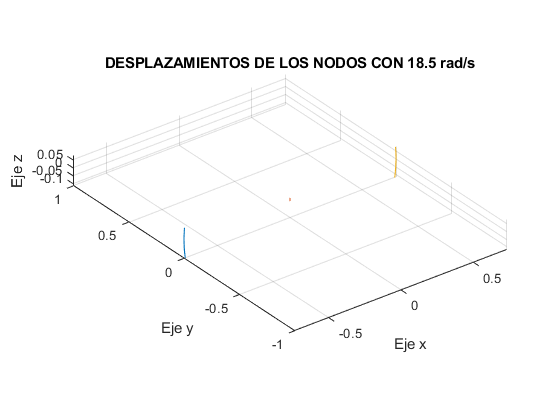

% Obtenemos una representación gráfica con los valores de X,Y y Z de los 3 nodos
% estudiados de la barra

% Realizar para cada simulatiom step para mostrar las diferencias

plot3(posiciones_nodo_0_6_5(:,1),posiciones_nodo_0_6_5(:,2),posiciones_nodo_0_6_5(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS CON 6.5 Nm')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_6_5(:,1),posiciones_nodo_28_6_5(:,2),posiciones_nodo_28_6_5(:,3))
plot3(posiciones_nodo_56_6_5(:,1),posiciones_nodo_56_6_5(:,2),posiciones_nodo_56_6_5(:,3))
hold off

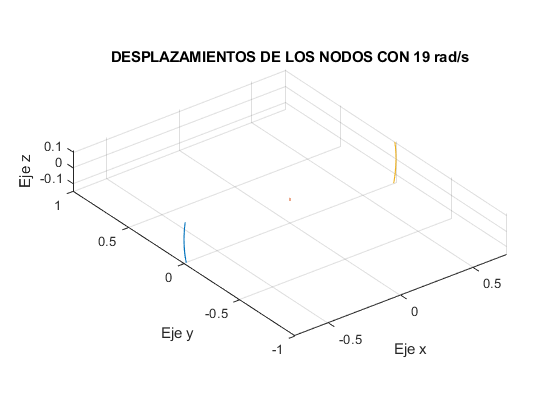


plot3(posiciones_nodo_0_7(:,1),posiciones_nodo_0_7(:,2),posiciones_nodo_0_7(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS CON 7 Nm')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_7(:,1),posiciones_nodo_28_7(:,2),posiciones_nodo_28_7(:,3))
plot3(posiciones_nodo_56_7(:,1),posiciones_nodo_56_7(:,2),posiciones_nodo_56_7(:,3))
hold off

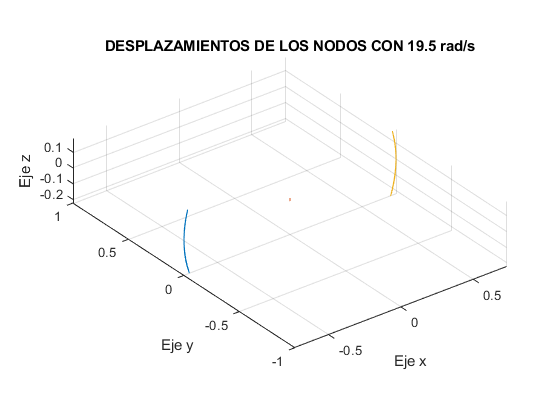


plot3(posiciones_nodo_0_7_5(:,1),posiciones_nodo_0_7_5(:,2),posiciones_nodo_0_7_5(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS CON 7.5 Nm')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_7_5(:,1),posiciones_nodo_28_7_5(:,2),posiciones_nodo_28_7_5(:,3))
plot3(posiciones_nodo_56_7_5(:,1),posiciones_nodo_56_7_5(:,2),posiciones_nodo_56_7_5(:,3))
hold off

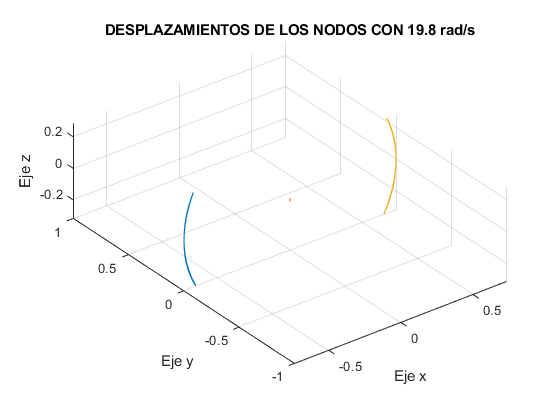


plot3(posiciones_nodo_0_7_8(:,1),posiciones_nodo_0_7_8(:,2),posiciones_nodo_0_7_8(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS CON 7.8 Nm')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_7_8(:,1),posiciones_nodo_28_7_8(:,2),posiciones_nodo_28_7_8(:,3))
plot3(posiciones_nodo_56_7_8(:,1),posiciones_nodo_56_7_8(:,2),posiciones_nodo_56_7_8(:,3))
hold off

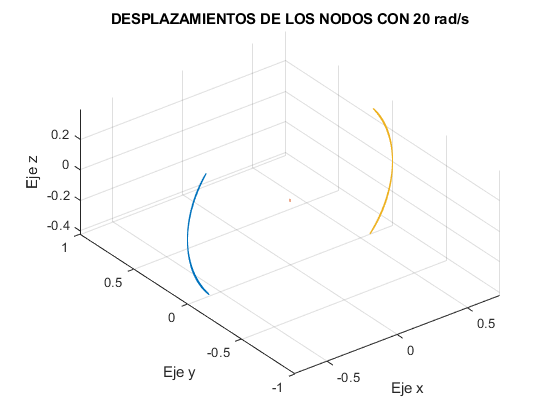


plot3(posiciones_nodo_0_8(:,1),posiciones_nodo_0_8(:,2),posiciones_nodo_0_8(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS CON 8 Nm')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_8(:,1),posiciones_nodo_28_8(:,2),posiciones_nodo_28_8(:,3))
plot3(posiciones_nodo_56_8(:,1),posiciones_nodo_56_8(:,2),posiciones_nodo_56_8(:,3))
hold off

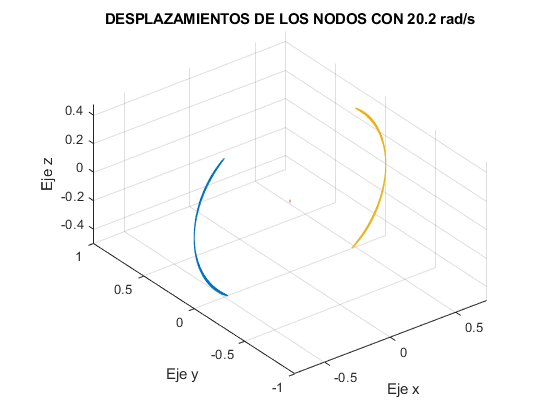


plot3(posiciones_nodo_0_8_2(:,1),posiciones_nodo_0_8_2(:,2),posiciones_nodo_0_8_2(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS CON 8.2 Nm')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_8_2(:,1),posiciones_nodo_28_8_2(:,2),posiciones_nodo_28_8_2(:,3))
plot3(posiciones_nodo_56_8_2(:,1),posiciones_nodo_56_8_2(:,2),posiciones_nodo_56_8_2(:,3))
hold off

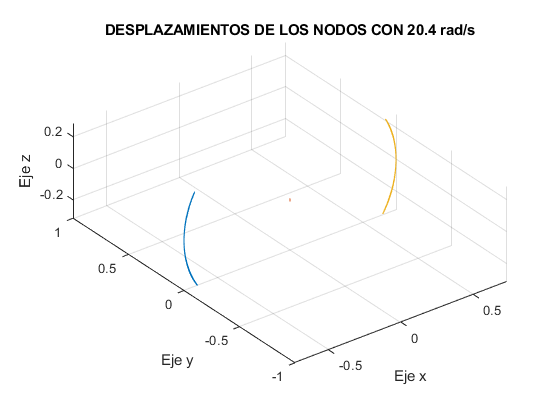


plot3(posiciones_nodo_0_8_4(:,1),posiciones_nodo_0_8_4(:,2),posiciones_nodo_0_8_4(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS CON 8.4 Nm')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_8_4(:,1),posiciones_nodo_28_8_4(:,2),posiciones_nodo_28_8_4(:,3))
plot3(posiciones_nodo_56_8_4(:,1),posiciones_nodo_56_8_4(:,2),posiciones_nodo_56_8_4(:,3))
hold off

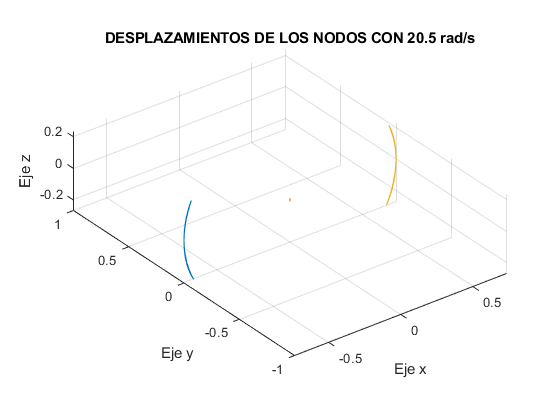


plot3(posiciones_nodo_0_8_5(:,1),posiciones_nodo_0_8_5(:,2),posiciones_nodo_0_8_5(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS CON 8.5 Nm')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_8_5(:,1),posiciones_nodo_28_8_5(:,2),posiciones_nodo_28_8_5(:,3))
plot3(posiciones_nodo_56_8_5(:,1),posiciones_nodo_56_8_5(:,2),posiciones_nodo_56_8_5(:,3))
hold off

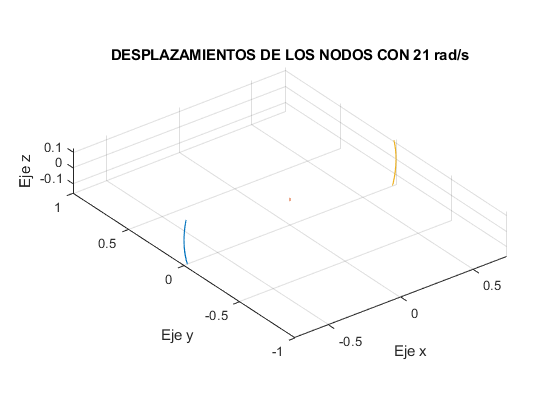


plot3(posiciones_nodo_0_9(:,1),posiciones_nodo_0_9(:,2),posiciones_nodo_0_9(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS CON 9 Nm')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_9(:,1),posiciones_nodo_28_9(:,2),posiciones_nodo_28_9(:,3))
plot3(posiciones_nodo_56_9(:,1),posiciones_nodo_56_9(:,2),posiciones_nodo_56_9(:,3))
hold off

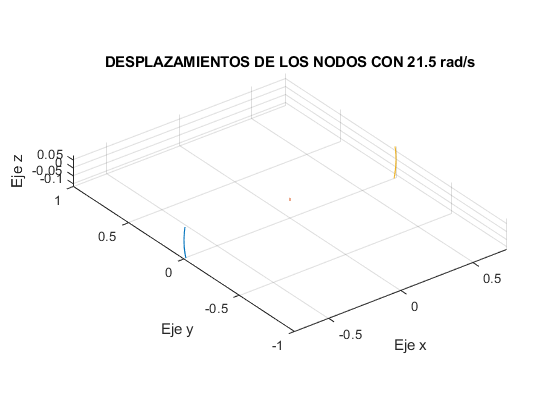


plot3(posiciones_nodo_0_9_5(:,1),posiciones_nodo_0_9_5(:,2),posiciones_nodo_0_9_5(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS CON 9.5 Nm')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_9_5(:,1),posiciones_nodo_28_9_5(:,2),posiciones_nodo_28_9_5(:,3))
plot3(posiciones_nodo_56_9_5(:,1),posiciones_nodo_56_9_5(:,2),posiciones_nodo_56_9_5(:,3))
hold off

## REPRESENTACIÓN DE ENERGÍA CINÉTICA PARA TODAS LAS FRECUENCIAS

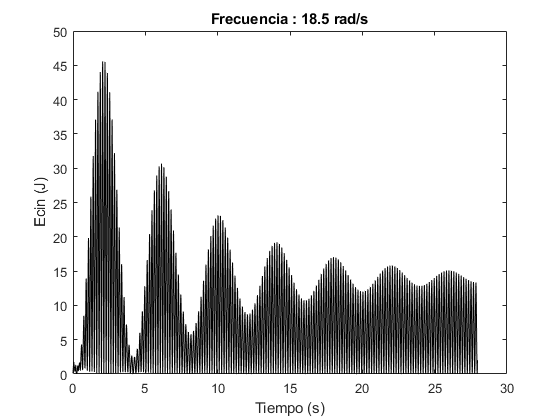

% Leemos los archivos procedentes de SOFA con los datos de energía cinética
% para las distintas frecuencias.
[vector_tiempo5,Ecin5] = readvars('Energy_6.5_wcin.txt');
[vector_tiempo1,Ecin1] = readvars('Energy_7.5_wcin.txt');
[vector_tiempo2,Ecin2] = readvars('Energy_7_wcin.txt');
[vector_tiempo6,Ecin6] = readvars('Energy_9_wcin.txt');
[vector_tiempo3,Ecin3] = readvars('Energy_8_wcin.txt');
[vector_tiempo9,Ecin9] = readvars('Energy_8.2_wcin.txt');
[vector_tiempo8,Ecin8] = readvars('Energy_8.4_wcin.txt');
[vector_tiempo4,Ecin4] = readvars('Energy_8.5_wcin.txt');
[vector_tiempo7,Ecin7] = readvars('Energy_9.5_wcin.txt');
[vector_tiempo10,Ecin10] = readvars('Energy_7.8_wcin.txt');

% Realizamos las representación de las distintas energías para cada
% frecuencia estudiada
plot(vector_tiempo5,Ecin5,'k')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Par : 6.5 Nm')

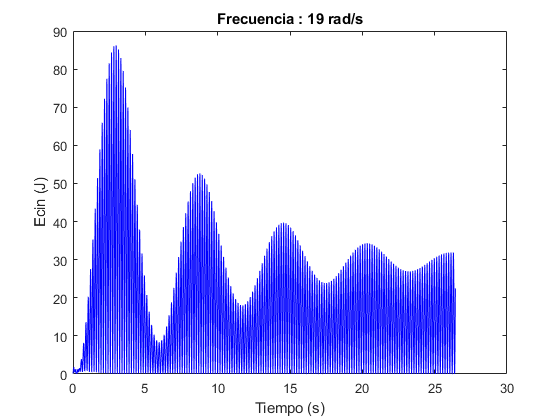

plot(vector_tiempo2,Ecin2,'b')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Par : 7 Nm')

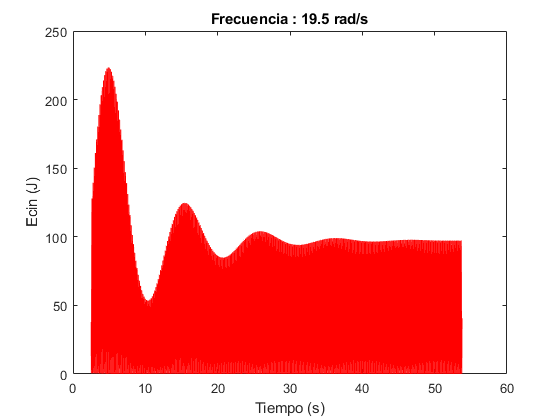

plot(vector_tiempo1,Ecin1,'r')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Par : 7.5 Nm')

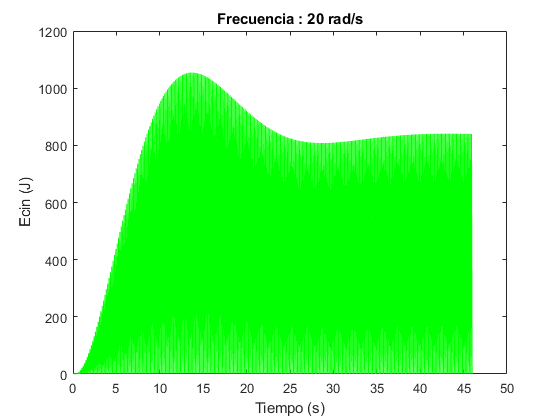

plot(vector_tiempo3,Ecin3,'g')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Par : 8 Nm')

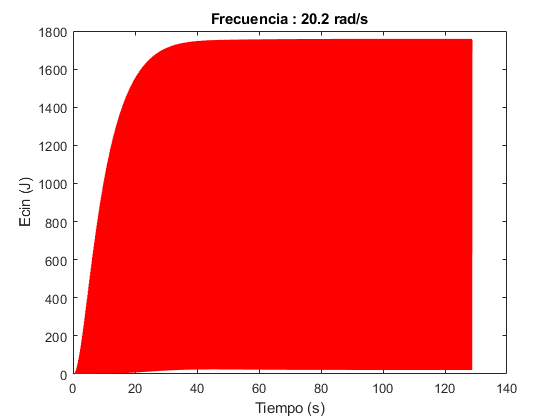

plot(vector_tiempo9,Ecin9,'r')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Par : 8.2 Nm')

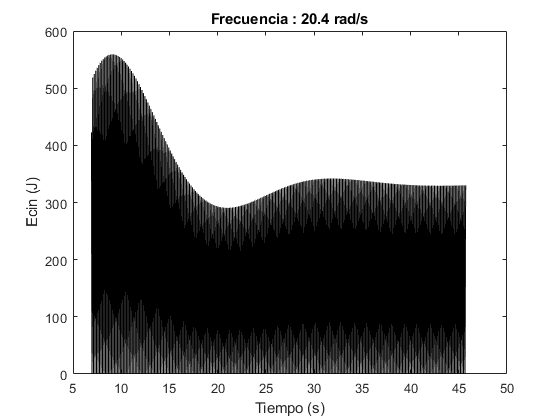

plot(vector_tiempo8,Ecin8,'k')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Par : 8.4 Nm')

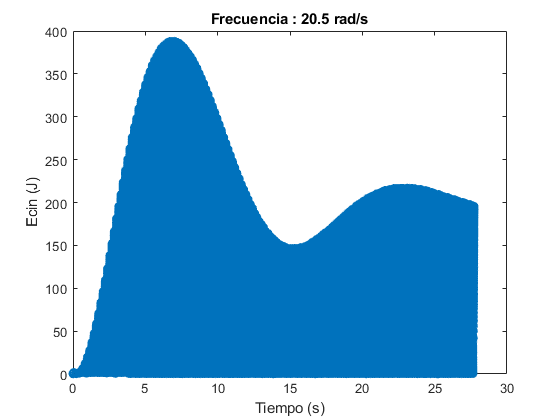

plot(vector_tiempo4,Ecin4,'o')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Par : 8.5 Nm')

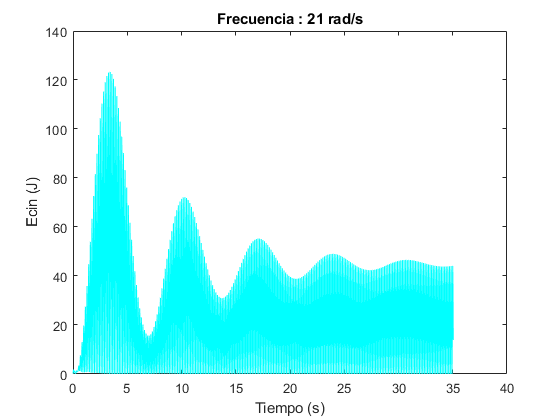

plot(vector_tiempo6,Ecin6,'c')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Par : 9 Nm')

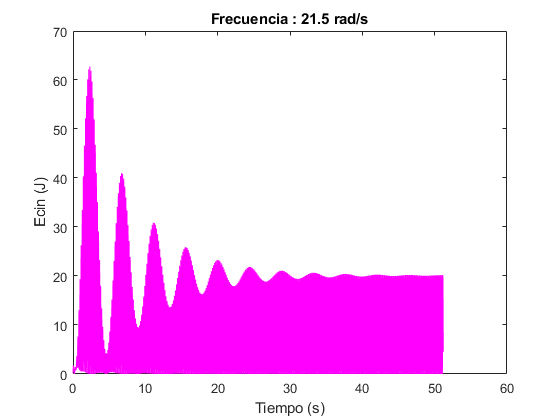

plot(vector_tiempo7,Ecin7,'m')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Par : 9.5 Nm')

## REPRESENTACIÓN DE ENERGÍAS POTENCIALES PARA TODAS LAS FRECUENCIAS

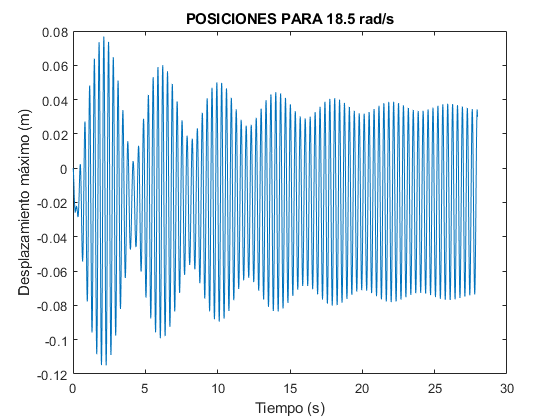

% Leemos los archivos procedentes de SOFA con los datos de las posiciones
% para las distintas frecuencias.

% Representamos primeros las posiciones en una grafica 2D
plot(vector_tiempo_6_5,posiciones_nodo_0_6_5(:,3))
title('POSICIONES PARA 6.5 Nm')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)')

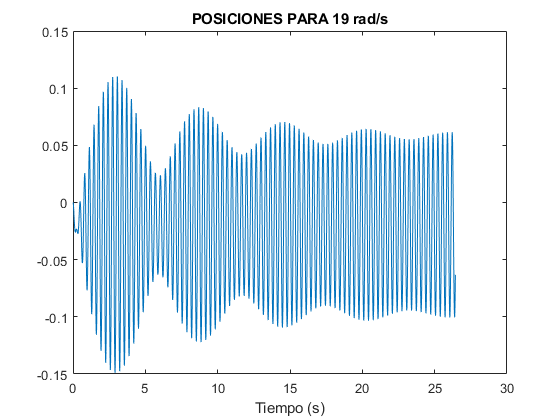


plot(vector_tiempo_7,posiciones_nodo_0_7(:,3))
title('POSICIONES PARA 7 Nm')
xlabel('Tiempo (s)')

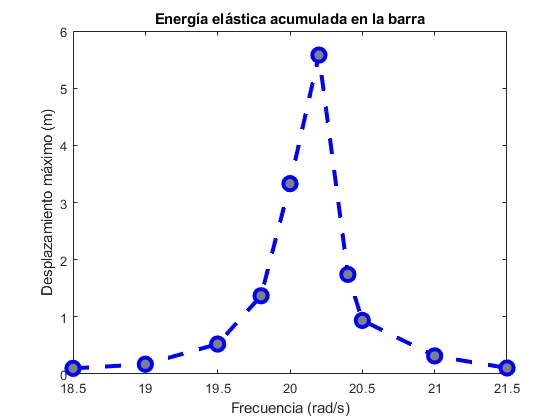

ylabel('Desplazamiento máximo (m)') 

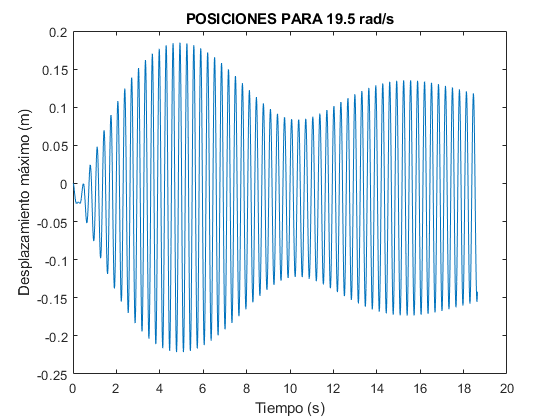


plot(vector_tiempo_7_5,posiciones_nodo_0_7_5(:,3))
title('POSICIONES PARA 7.5 Nm')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

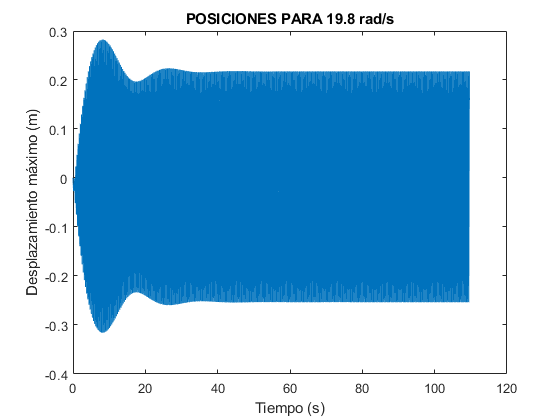


plot(vector_tiempo_7_8,posiciones_nodo_0_7_8(:,3))
title('POSICIONES PARA 7.8 Nm')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

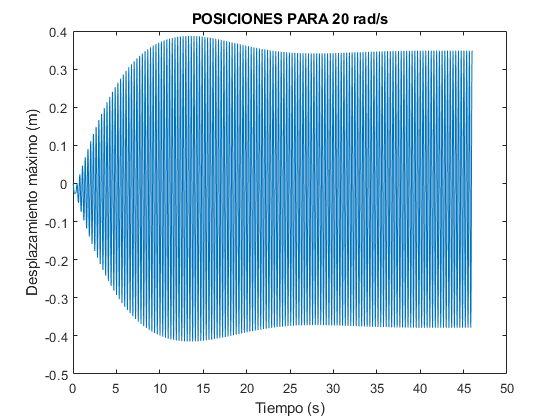


plot(vector_tiempo_8,posiciones_nodo_0_8(:,3))
title('POSICIONES PARA 8 Nm')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

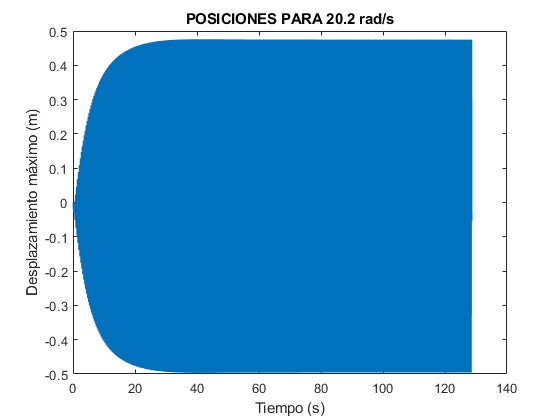


plot(vector_tiempo_8_2,posiciones_nodo_0_8_2(:,3))
title('POSICIONES PARA 8.2 Nm')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

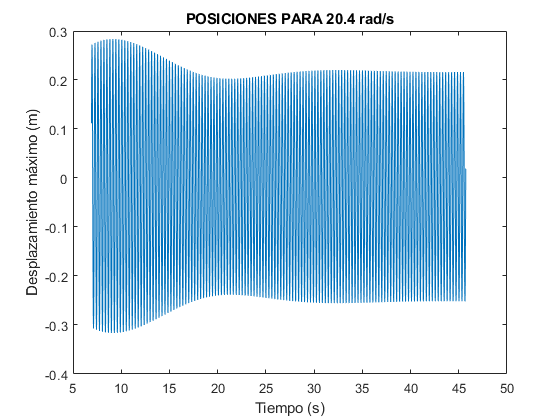


plot(vector_tiempo_8_4,posiciones_nodo_0_8_4(:,3))
title('POSICIONES PARA 8.4 Nm')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

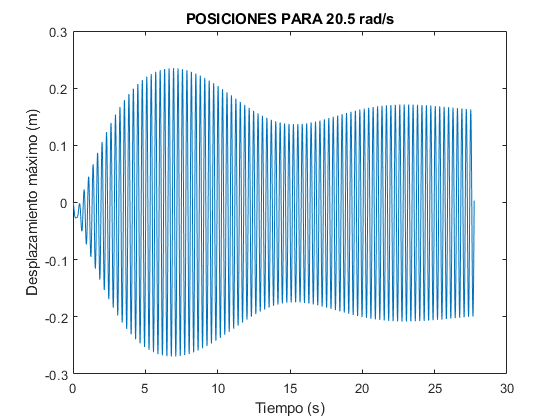


plot(vector_tiempo_8_5,posiciones_nodo_0_8_5(:,3))
title('POSICIONES PARA 8.5 Nm')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

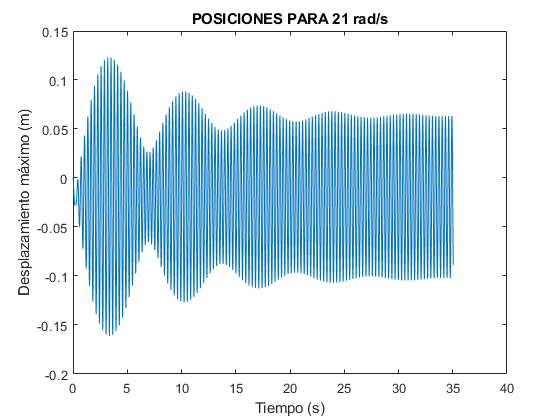


plot(vector_tiempo_9,posiciones_nodo_0_9(:,3))
title('POSICIONES PARA 9 Nm')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

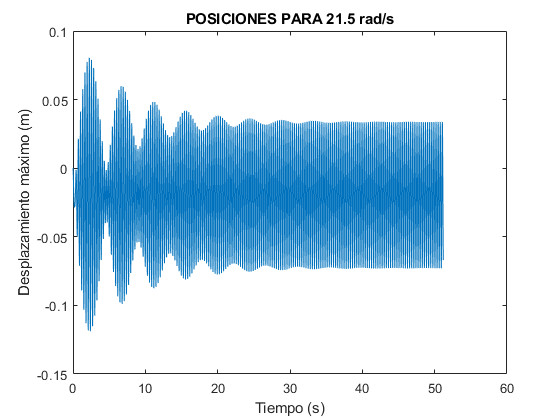


plot(vector_tiempo_9_5,posiciones_nodo_0_9_5(:,3))
title('POSICIONES PARA 9.5 Nm')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)')


% Realizamos las representación de las distintas energías para cada
% frecuencia estudiada
n=1

n = 1

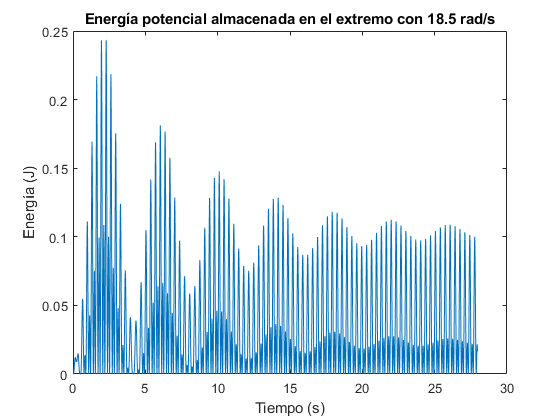

for i=1:length(posicion_nodo_0_dcha_split_6_5)
    % Calculamos la energía potencial
    Ep6_5(i) = 2*18.4339*0.5*(posiciones_nodo_0_6_5(i,3))^2;
    if (vector_tiempo_6_5(i,1)>15.2)
        % Almacenamos los valores estacionarios
        Ep6_5_(i) = 2*18.4339*0.5*(posiciones_nodo_0_6_5(i,3))^2;
        n = n + 1;
    end
end
plot(vector_tiempo_6_5,Ep6_5)
title('Energía potencial almacenada en el extremo con 6.5 Nm')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

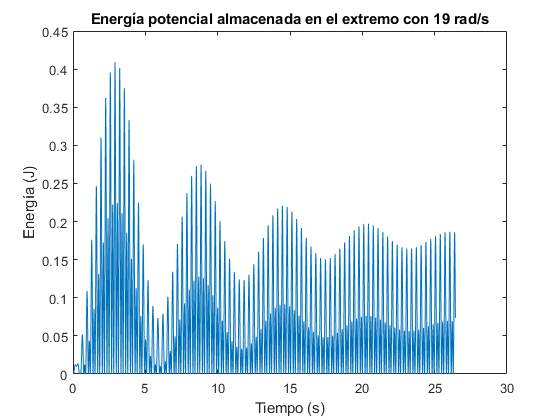

n = 1;
for i=1:length(posicion_nodo_0_dcha_split_7)
    Ep7(i) = 2*18.4339*0.5*(posiciones_nodo_0_7(i,3))^2;
    if (vector_tiempo_7(i,1)>16.1)
        Ep7_(i) = 2*18.4339*0.5*(posiciones_nodo_0_7(i,3))^2;
        n = n + 1;
    end
end
plot(vector_tiempo_7,Ep7)
title('Energía potencial almacenada en el extremo con 7 Nm')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

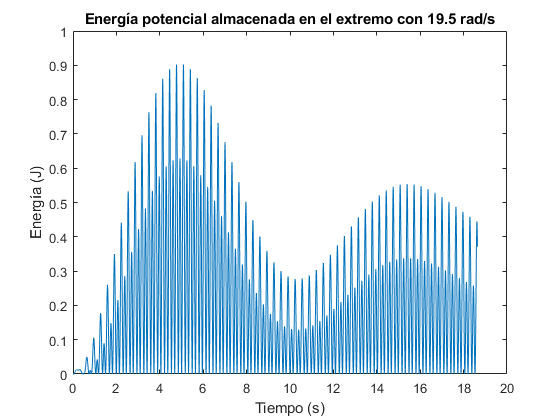

n = 1;
for i=1:length(posicion_nodo_0_dcha_split_7_5)
    Ep7_5(i) = 2*18.4339*0.5*(posiciones_nodo_0_7_5(i,3))^2;
    if (vector_tiempo_7_5(i,1)>8.3)
        Ep7_5_(i) = 2*18.4339*0.5*(posiciones_nodo_0_7_5(i,3))^2;
        n = n + 1;
    end
end
plot(vector_tiempo_7_5,Ep7_5)
title('Energía potencial almacenada en el extremo con 7.5 Nm')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

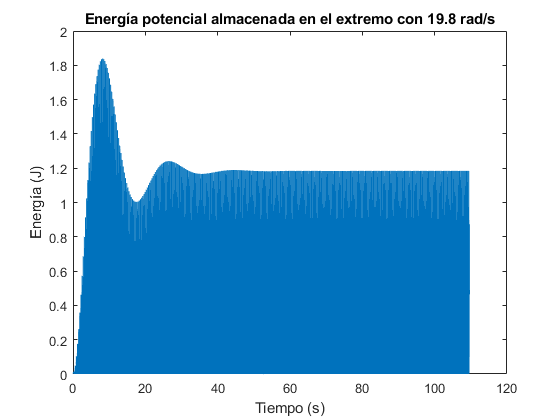

n = 1;
for i=1:length(posicion_nodo_0_dcha_split_7_8)
    Ep7_8(i) = 2*18.4339*0.5*(posiciones_nodo_0_7_8(i,3))^2;
    if (vector_tiempo_7_8(i,1)>60)
        Ep7_8_(i) = 2*18.4339*0.5*(posiciones_nodo_0_7_8(i,3))^2;
        n = n + 1;
    end
end
plot(vector_tiempo_7_8,Ep7_8)
title('Energía potencial almacenada en el extremo con 7.8 Nm')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

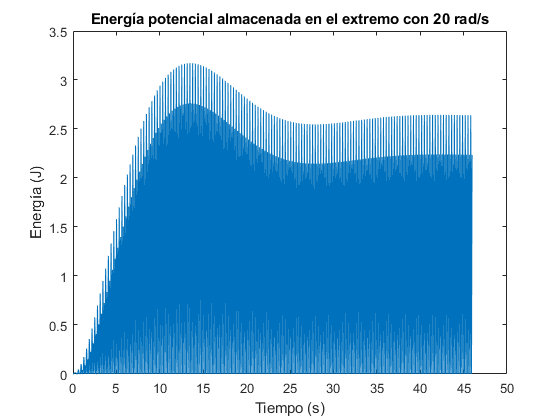

n = 1;
for i=1:length(posicion_nodo_0_dcha_split_8)
    Ep8(i) = 2*18.4339*0.5*(posiciones_nodo_0_8(i,3))^2;
    if (vector_tiempo_8(i,1)>24)
        Ep8_(i) = 2*18.4339*0.5*(posiciones_nodo_0_8(i,3))^2;
        n = n + 1;
    end
end
plot(vector_tiempo_8,Ep8)
title('Energía potencial almacenada en el extremo con 8 Nm')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

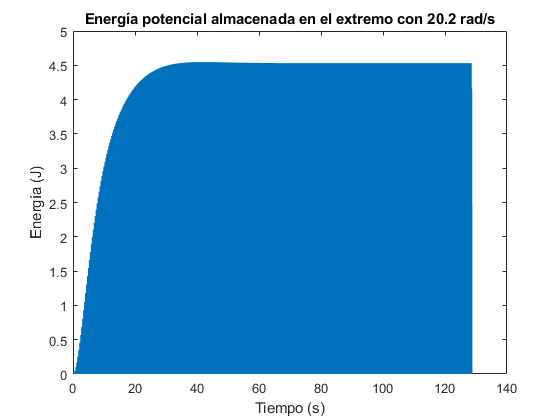

n = 1;
for i=1:length(posicion_nodo_0_dcha_split_8_2)
    Ep8_2(i) = 2*18.4339*0.5*(posiciones_nodo_0_8_2(i,3))^2;
    if (vector_tiempo_8_2(i,1)>80)
        Ep8_2_(i) = 2*18.4339*0.5*(posiciones_nodo_0_8_2(i,3))^2;
        n = n + 1;
    end
end
plot(vector_tiempo_8_2,Ep8_2)
title('Energía potencial almacenada en el extremo con 8.2 Nm')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

n=1

n = 1

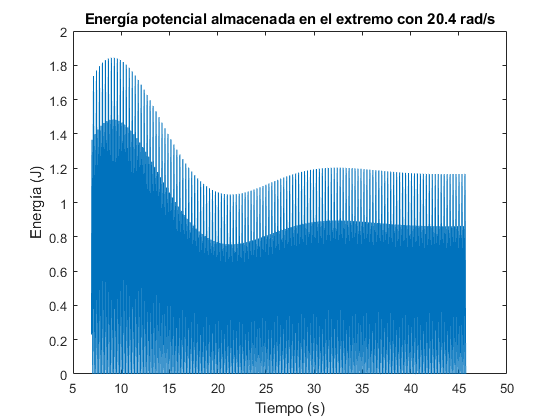

for i=1:length(posicion_nodo_0_dcha_split_8_4)
    Ep8_4(i) = 2*18.4339*0.5*(posiciones_nodo_0_8_4(i,3))^2;
    if (vector_tiempo_8_4(i,1)>17.5)
        Ep8_4_(i) = 2*18.4339*0.5*(posiciones_nodo_0_8_4(i,3))^2;
        n = n + 1;
    end
end
plot(vector_tiempo_8_4,Ep8_4)
title('Energía potencial almacenada en el extremo con 8.4 Nm')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

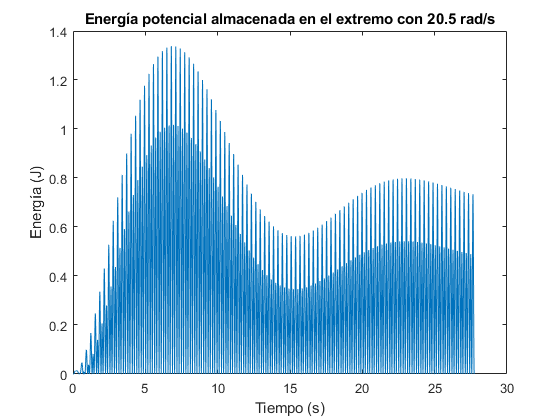

n = 1;
for i=1:length(posicion_nodo_0_dcha_split_8_5)
    Ep8_5(i) = 2*18.4339*0.5*(posiciones_nodo_0_8_5(i,3))^2;
    if (vector_tiempo_8_5(i,1)>11.5)
        Ep8_5_(i) = 2*18.4339*0.5*(posiciones_nodo_0_8_5(i,3))^2;
        n = n + 1;
    end
end
plot(vector_tiempo_8_5,Ep8_5)
title('Energía potencial almacenada en el extremo con 8.5 Nm')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

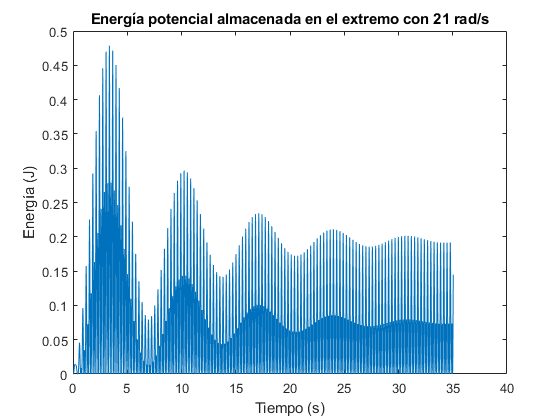

n = 1;
for i=1:length(posicion_nodo_0_dcha_split_9)
    Ep9(i) = 2*18.4339*0.5*(posiciones_nodo_0_9(i,3))^2;
    if (vector_tiempo_9(i,1)>17.2)
        Ep9_(n) = 2*18.4339*0.5*(posiciones_nodo_0_9(i,3))^2;
        n = n + 1;
    end
end
plot(vector_tiempo_9,Ep9)
title('Energía potencial almacenada en el extremo con 9 Nm')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

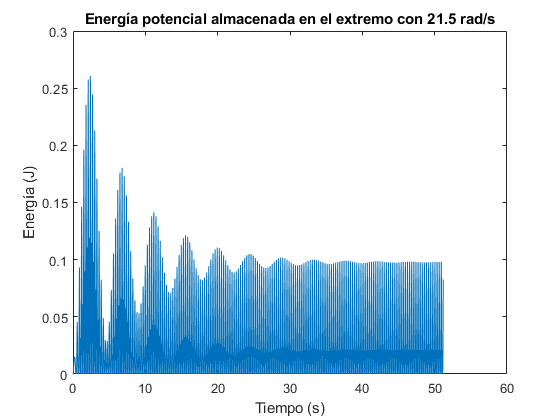

n = 1;
for i=1:length(posicion_nodo_0_dcha_split_9_5)
    Ep9_5(i) = 2*18.4339*0.5*(posiciones_nodo_0_9_5(i,3))^2;
    if (vector_tiempo_9_5(i,1)>40)
        Ep9_5_(n) = 2*18.4339*0.5*(posiciones_nodo_0_9_5(i,3))^2;
        n = n + 1;
    end
end
plot(vector_tiempo_9_5,Ep9_5)
title('Energía potencial almacenada en el extremo con 9.5 Nm')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

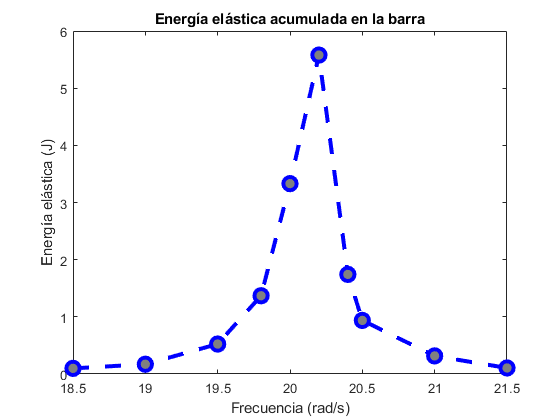

n = 1;

% Hallamos el valor de RMS
Ep6_5_rms = rms(Ep6_5_);
Ep7_rms = rms(Ep7_);
Ep7_5_rms = rms(Ep7_5_);
Ep7_8_rms = rms(Ep7_8_);
Ep8_rms = rms(Ep8_);
Ep8_2_rms = rms(Ep8_2_);
Ep8_4_rms = rms(Ep8_4_);
Ep8_5_rms = rms(Ep8_5_);
Ep9_rms = rms(Ep9_);
Ep9_5_rms = rms(Ep9_5_);

% Agrupamos los valores de energía potencial
Ep_rms = [Ep6_5_rms, Ep7_rms, Ep7_5_rms, Ep7_8_rms, Ep8_rms, Ep8_2_rms, Ep8_4_rms, Ep8_5_rms, Ep9_rms, Ep9_5_rms];

% Almacenamos los valores de frecuencias
par = [6.5,7,7.5,7.8,8,8.2,8.4,8.5,9 9.5]';
omega = [18.48 19.04];

% Aplicamos la reducción a 1 seg
T = 2*pi./par;
scale_to_seg = 1./T;
Elastic_Energy = Ep_rms'.*scale_to_seg; % Energía usada en 1 seg

% Representamos la energía potencial escalada y lista para la comparación
plot(omega,Elastic_Energy,'--bo',...
    'LineWidth',3,...
    'MarkerSize',10,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0.5,0.5,0.5]);
title('Energía elástica acumulada en la barra')
xlabel('Frecuencia (rad/s)')
ylabel('Energía elástica (J)')


plot(par,Elastic_Energy,'--bo',...
    'LineWidth',3,...
    'MarkerSize',10,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0.5,0.5,0.5]);
title('Energía elástica acumulada en la barra')
xlabel('Par (Nm)')
ylabel('Energía elástica (J)')